# Cart-Pole Problem

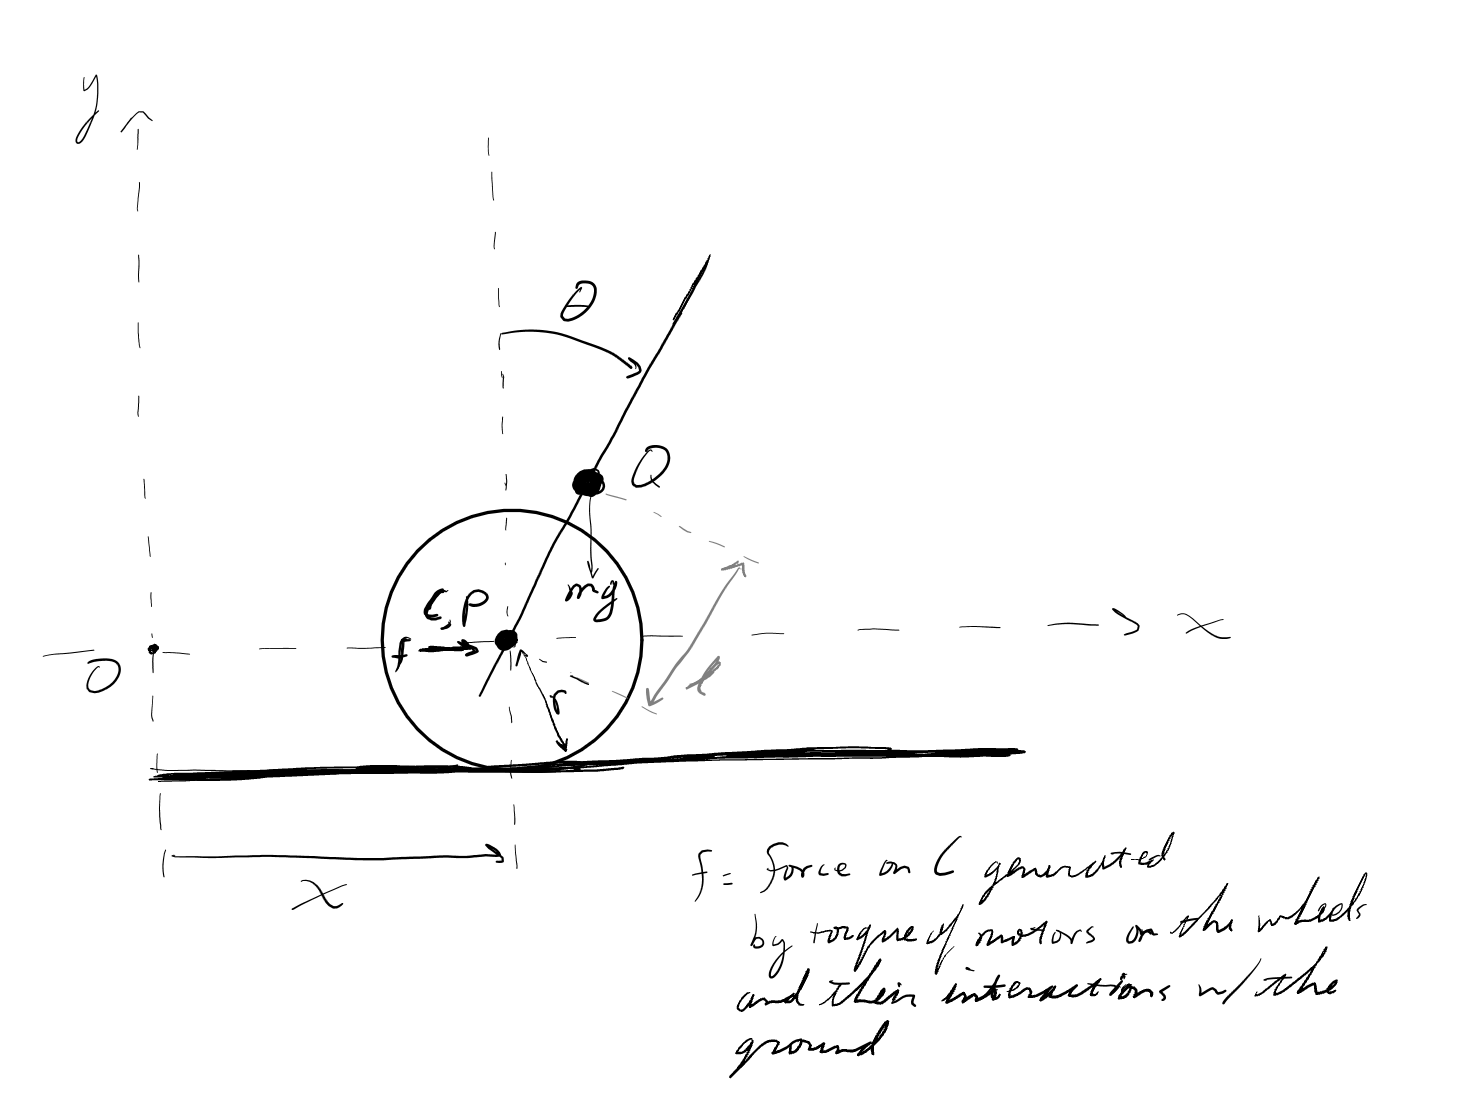

The equations of motion for the cart and the pole are as follows, where:

g = gravity = 9.8 m/s^2

J = inertial constant of the pole

x = cart position

th = theta = pole angle w.r.t. vertical up, +90deg when horizontal to the right

m = mass of the pole

m_c = mass of the cart

M = m + m_c

mu_c = friction coefficient of the cart

r = radius of the cart wheels

f = force applied to the cart (via the torque generated by its motors)

l = location of the CoM of the pole

O = origin

Q = CoM of the pole

P = pivot point of the pole

C = CoM of the Cart

syms m_c m x_ddot x_dot x theta_ddot theta_dot theta l mu_c J g f r
% eqtn 12-F
M= m_c + m;
Ff = -mu_c*M*g*x_dot/r; % look more closely at friction and how it applies force to the cart's movement
eqn_cart = m_c*x_ddot + m*(l*theta_ddot*cos(theta) - l*theta_dot^2*sin(theta) + x_ddot) - Ff == f

$$eqn\_cart = m\,\left(-l\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+\ddot{x}+l\,\ddot{\theta }\,\cos\left(\theta \right)\right)+m_{c}\,\ddot{x}+\frac{g\,\mu_{c}\,\dot{x}\,\left(m+m_{c}\right)}{r}=f$$

eqn_pend = m*l*(l*theta_ddot + x_ddot*cos(theta)) - m*l*sin(theta) + J*theta_ddot == 0

$$eqn\_pend = J\,\ddot{\theta }-l\,m\,\sin\left(\theta \right)+l\,m\,\left(l\,\ddot{\theta }+\ddot{x}\,\cos\left(\theta \right)\right)=0$$


% Deriving the solutions for ONLY x_ddot and theta_ddot
[x_ddot_sol, theta_ddot_sol] = solve([eqn_pend,eqn_cart],[x_ddot,theta_ddot])

$$x\_ddot\_sol = -\frac{l^{2}\,m^{2}\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)-f\,l^{2}\,m\,r-l^{3}\,m^{2}\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)-J\,f\,r+g\,l^{2}\,m^{2}\,\mu_{c}\,\dot{x}+J\,g\,m\,\mu_{c}\,\dot{x}+J\,g\,m_{c}\,\mu_{c}\,\dot{x}+g\,l^{2}\,m\,m_{c}\,\mu_{c}\,\dot{x}-J\,l\,m\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{r\,\left(-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c}\right)}$$

$$theta\_ddot\_sol = \frac{l\,m\,\left(-l\,m\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-f\,r\,\cos\left(\theta \right)+m\,r\,\sin\left(\theta \right)+m_{c}\,r\,\sin\left(\theta \right)+g\,m\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)+g\,m_{c}\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)\right)}{r\,\left(-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c}\right)}$$

## Setting up the State-space equations

syms beta_1 beta_2 beta_3 beta_4 u t
% f = [beta_1_dot; beta_2_dot; beta_3_dot; beta_4_dot] 
%   = [x_dot; x_ddot; theta_dot; theta_ddot]
ss_x_theta = [x_dot;
    x_ddot_sol;
    theta_dot;
    theta_ddot_sol]

$$ss\_x\_theta = \begin{array}{l} \left(\begin{array}{c} \dot{x}\\ -\frac{l^{2}\,m^{2}\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)-f\,l^{2}\,m\,r-l^{3}\,m^{2}\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)-J\,f\,r+g\,l^{2}\,m^{2}\,\mu_{c}\,\dot{x}+J\,g\,m\,\mu_{c}\,\dot{x}+J\,g\,m_{c}\,\mu_{c}\,\dot{x}+g\,l^{2}\,m\,m_{c}\,\mu_{c}\,\dot{x}-J\,l\,m\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{\sigma_{1}}\\ \dot{\theta }\\ \frac{l\,m\,\left(-l\,m\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-f\,r\,\cos\left(\theta \right)+m\,r\,\sin\left(\theta \right)+m_{c}\,r\,\sin\left(\theta \right)+g\,m\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)+g\,m_{c}\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r\,\left(-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c}\right) \end{array}$$

ss_beta = subs(ss_x_theta,[x, x_dot, theta, theta_dot, f],[beta_1, beta_2, beta_3, beta_4, u]);
beta = [beta_1; beta_2; beta_3; beta_4];
% Linearize the system
% per Lecture 2 of ME6401 Linear Controls, take the Jacobian of the system
% of equations to get the partial differential wrt each state variable, and
% the input variable
Asym = jacobian(ss_beta,beta)

Bsym = jacobian(ss_beta,u)

$$Bsym = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{m\,r\,l^{2}+J\,r}{r\,\sigma_{1}}\\ 0\\ -\frac{l\,m\,\cos\left(\beta_{3}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,m^{2}\,{\cos\left(\beta_{3}\right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c} \end{array}$$


% per problem diagram, setting equilibrium point at theta = 0 (vertical) and
% arbitrarily selecting x = 0 for simplicity
A0 = subs(Asym,[beta_1, beta_2, beta_3, beta_4], [0, 0, 0, 0])

$$A0 = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{g\,\mu_{c}\,l^{2}\,m^{2}+g\,m_{c}\,\mu_{c}\,l^{2}\,m+J\,g\,\mu_{c}\,m+J\,g\,m_{c}\,\mu_{c}}{r\,\sigma_{1}} & -\frac{l^{2}\,m^{2}}{\sigma_{1}} & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{l\,m\,\left(g\,m\,\mu_{c}+g\,m_{c}\,\mu_{c}\right)}{r\,\sigma_{1}} & \frac{l\,m\,\left(m\,r+m_{c}\,r\right)}{r\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m\,m_{c}\,l^{2}+J\,m+J\,m_{c} \end{array}$$

B0 = subs(Bsym,[beta_1, beta_2, beta_3, beta_4], [0, 0, 0, 0])

$$B0 = \left(\begin{array}{c} 0\\ \frac{m\,r\,l^{2}+J\,r}{r\,\left(m\,m_{c}\,l^{2}+J\,m+J\,m_{c}\right)}\\ 0\\ -\frac{l\,m}{m\,m_{c}\,l^{2}+J\,m+J\,m_{c}} \end{array}\right)$$


% Thus, our linearized state-space representation of the system can be
% represented as: diff(beta,t) = A0*beta + B0*u

% where beta_3 is the deviation from the equil point, theta = 0

## Inserting real values and creating the State Space object

g_real = 9.8; % [m/sec^2]
m_motor = 9.5*2/1000; % [kg] documentation
m_bump = 35/1000; % [kg] documentation
m_batt = 138/1000; % [kg] measured
m_wheels = 39.7/1000; % [kg] documentation
m_cb = (200/1000 - m_motor - m_bump - m_wheels); % [kg] measured value
m_c_real = (m_wheels); % [kg] - mass of cart (i.e. the wheels of the seqway)
m_real = m_motor + m_bump + m_batt + m_cb; % [kg] - mass of "pole"
mu_c_real = 0.02; % bearing viscous friction coeff. for rotational speed

% Calculating CoM of the pole w.r.t. location of axis of rotation
x_rot = 31; % [mm] axis of rotation is NOT at the bottom of the pole
x_motor = 0; % [mm] motor w.r.t. rotation axis
l_cb = 109.2; % [mm] lengh of control board
x_cb = l_cb/2 - x_rot; % [mm] control board w.r.t. rotation axis
l_batt = 95.7; % [mm] length of batteries
x_batt = l_batt/2 - x_rot + 2.5; % [mm] batteries w.r.t. rotation axis
x_bump = l_cb - 30 + 40 - x_rot; % [mm] bumpers w.r.t. rotation axis
y_motor = 16.416; y_cb = 0; y_batt = 0; y_bump = 0; %  w.r.t. rotation axis
CM_x_rot = (m_motor*x_motor + m_cb*x_cb + m_batt*x_batt + m_bump*x_bump)/(m_real);
CM_y_rot = y_motor*m_motor/m_real;
CM_rot = sqrt(CM_x_rot^2 + CM_y_rot^2); % [mm] length from CM of pole to axis of rotation

l_real = CM_rot/1000; % [m] - length to pole CoM

% Calculating Inertia of the Pole:
I_motor = m_motor*y_motor^2; % [kg mm^2] point mass inertia of motors
I_bump = m_bump*x_bump^2; % [kg mm^2] point mass inertia of bumpers
% Parallel axis theorem: I = Icm + m h^2
% Inertia of a pole of equally distributed mass about one end: I = m l^2/3 
% Inertia of a pole of equally distributed mass about the CoM: I = m l^2/12
I_batt = m_batt*(l_batt/2)^2/12 + m_batt*x_batt^2; % [kg mm^2] inertia of batteries
I_cb = m_cb*(l_cb/2)^2/12 + m_cb*x_cb^2; % [kg mm^2] inertia of control board

J_real = (I_motor + I_bump + I_batt + I_cb)*(1/1000)^2; % kg*m^2 - mass moment of inertia of the pole (1/12*m*(length)^2)

r_real = 40/1000; % [mm]

symvar(A0)

$$ans = \left(\begin{array}{ccccccc} J & g & l & m & m_{c} & \mu_{c} & r \end{array}\right)$$

A = double(subs(A0,[g,m_c,m,mu_c,l,J,r],[g_real,m_c_real,m_real,mu_c_real,l_real,J_real,r_real]));
B = double(subs(B0,[g,m_c,m,mu_c,l,J],[g_real,m_c_real,m_real,mu_c_real,l_real,J_real]));
% outputting both the x-position and theta-angle
C = [1 0 0 0; 0 0 1 0];
D = [0;0];
states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'u'};
outputs = {'x'; 'theta'};
olsys = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

olsys =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot          0    -7.02  -0.4326        0
   phi            0        0        0        1
   phi_dot        0    86.62    17.68        0
 
  B = 
                u
   x            0
   x_dot    4.238
   phi          0
   phi_dot  -52.3
 
  C = 
                x    x_dot      phi  phi_dot
   x            1        0        0        0
   theta        0        0        1        0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.



% initial(olsys,[0;0;7*pi/8;0],10) % this system blows up because we
% LINEARIZED around pi (vertical up), not 0 (vertical down)
olsys_tf = tf(olsys)

olsys_tf =
 
  From input "u" to output...
          4.238 s^2 + 3.765e-15 s - 52.3
   x:  ------------------------------------
       s^4 + 7.02 s^3 - 17.68 s^2 - 86.62 s
 
                       -52.3 s
   theta:  --------------------------------
           s^3 + 7.02 s^2 - 17.68 s - 86.62
 
Continuous-time transfer function.



## Stabilizing the System with SS Feedback gain

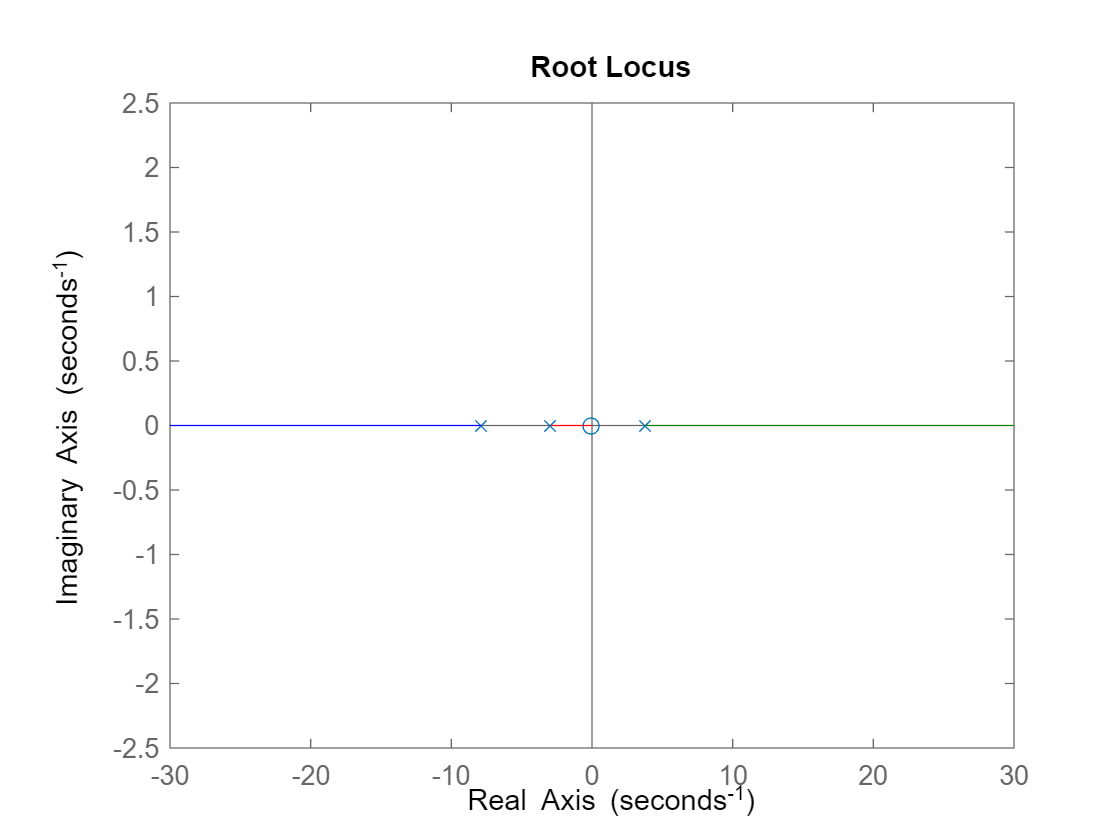

figure;
rlocus(olsys_tf(2))

% from the root locus plot theta/u, we see that there will always be a pole
% in the RHP, so we have to do a state-space feedback to stabilize the system

% seeing if the system is controllable and observable (full rank = yes)
rank(ctrb(A,B))

ans = 4

rank(obsv(A,C))

ans = 4


p = [-3, -4, -5, -6];
K = acker(A,B,p)

K =    -6.8836   -8.1956   -3.1713   -0.8742


Abar = A-B*K;
clsys = ss(Abar,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

clsys =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot      29.18    27.72    13.01    3.705
   phi            0        0        0        1
   phi_dot     -360     -342   -148.2   -45.72
 
  B = 
                u
   x            0
   x_dot    4.238
   phi          0
   phi_dot  -52.3
 
  C = 
                x    x_dot      phi  phi_dot
   x            1        0        0        0
   theta        0        0        1        0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.



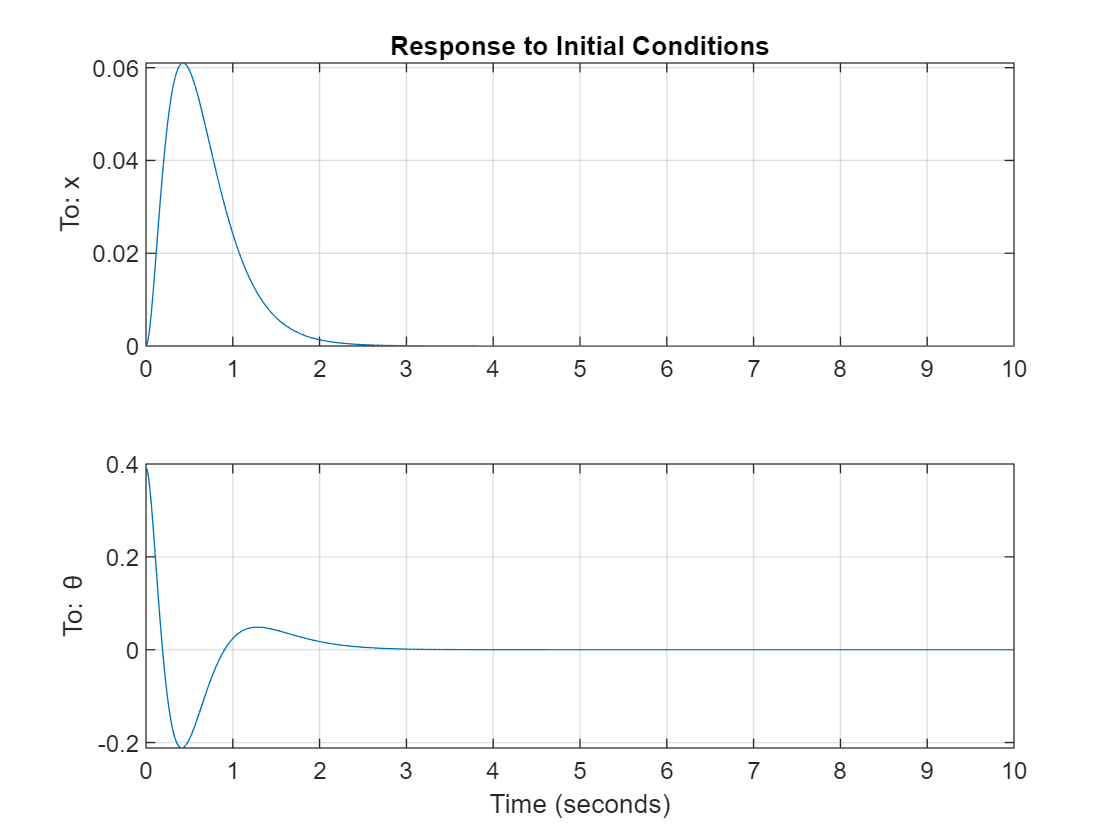

[y_init,t_init,beta_state_init] = initial(clsys,[0;0;pi/8;0],10);
figure;
tiledlayout(2,1);
nexttile;
plot(t_init, y_init(:,1)); title('Response to Initial Conditions'); ylabel('To: x');
grid on
nexttile;
plot(t_init,y_init(:,2)); ylabel('To: \theta'); xlabel('Time (seconds)')
grid on

## Desired output tracking

yd = [1; 0]; % x position: 1m, phi: 0rad deviation
clsys_gain = -C/Abar*B % this is the gain of the system with a step input

clsys_gain =    -0.1453
         0


% from clsys_gain, we can see that phi will always return to 0, so we can
% only control the output x:
r1 = yd(1)/clsys_gain(1); % reference input

figure;
% step response with defined input so that output is at desired location
[y,t,beta_state] = step(clsys*r1);

### Animating the desired output tracking - NEXT STEP

x = beta_state_init(:,1);
theta = beta_state_init(:,3);
slen = 0.2;
sq = [  -slen  slen   slen   -slen  -slen;
        0   0   slen   slen   0]; % the vertex locations of the cart
figure;
cart = plot(sq(1,:),sq(2,:),'r');
hold on

th = linspace(0,2*pi) ; % the points for generating the plot of a circle
r1 = 0.01; % radius of circle 1 (CoM)..?

cB = [0; l_real]; % initial x-axis location of the pole CoM, B-frame
eB = 2*cB; % initial x-axis location of the END of the pole 
R_AB = [cos(theta(1)) sin(theta(1)); -sin(theta(1)) cos(theta(1))]; % rotational matrix
d_AB = [0; slen]; % location of center of B-frame w.r.t. A-frame
g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
cA = g_AB*[cB; 1]; cA = cA(1:2);

eA = g_AB*[eB; 1]; eA = eA(1:2);

CoMx = cA(1) + r1*cos(th) ; 
CoMy = cA(2) + r1*sin(th) ;

CoM = plot(CoMx,CoMy,'bl') ;
bar = plot([d_AB(1) eA(1)], [d_AB(2) eA(2)],'b')

bar =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0212]
              YData: [0.2000 0.2512]
              ZData: [1×0 double]

  Show all properties


axis equal
minx = min(x)-slen;
maxx = max(x)+slen;
axis([minx maxx 0 1]) 

%% animation
for i = 2:length(x)
    sq_draw = sq + [repmat(x(i),[1,size(sq,2)]); zeros(1,size(sq,2))];
    
    R_AB = [cos(theta(i)) -sin(theta(i)); sin(theta(i)) cos(theta(i))]; % rotational matrix
    d_AB = [x(i); slen]; % location of center of B-frame w.r.t. A-frame
    g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
    cA = g_AB*[cB; 1]; cA = cA(1:2);
    eA = g_AB*[eB; 1]; eA = eA(1:2);
    
    CoMx = cA(1) + r1*cos(th) ; 
    CoMy = cA(2) + r1*sin(th) ;
    bar_x = [d_AB(1) eA(1)];
    bar_y = [d_AB(2) eA(2)];

    set(cart,'XData',sq_draw(1,:),'YData',sq_draw(2,:)) ;
    set(CoM,'XData',CoMx,'YData',CoMy) ;
    set(bar,'XData',bar_x,'YData',bar_y) ;
    axis([minx maxx 0 1])     
    drawnow
    pause(0.05)
end


**Done: Figure out why the angle is negative from the simulation... (it was my definition of the rotation matrix)**

NEXT STEPS:

- Substitute in real values (estimated)

- get the integral control working, 

- discretize the control solutions (state space, integral, optimal)

- Start coding into arduino and test; tune values as needed

- (? then do an optimal control solution ?)

- write up the derivation of the equations of motion with references so when I show this to someone else it's very clear (like I've written a paper or something on it)